**Train**

normalFiles = dir("Train_2/Normal/*.wav");
faultyFiles = dir("Train_2/Faulty/*.wav");

numNormalSamples = length(normalFiles);
numFaultySamples = length(faultyFiles);

% Prepare input and label matrices
xFiles = [normalFiles; faultyFiles];
y = [repmat({'N'}, numNormalSamples, 1)
     repmat({'F'}, numFaultySamples, 1)];

y = categorical(y);

numSamples = length(y);
idx = randperm(numSamples);
newData = xFiles(idx, :);
newLabels = y(idx);

% Split training data into a training set and a test set
partition = cvpartition(newLabels, 'Holdout', 0.2);

idxTrain = training(partition);
idxTest = test(partition);

XTrain = newData(idxTrain);
yTrain = newLabels(idxTrain);

XTest = newData(idxTest);
yTest = newLabels(idxTest);

% Split the test set further into a validation set and a smaller test set
partition = cvpartition(yTest, 'Holdout', 0.5);

idxVal = training(partition);
idxTest = test(partition);

XVal = XTest(idxVal);
yVal = yTest(idxVal);

XTest = XTest(idxTest);
yTest = yTest(idxTest);

function spec = extractSpectrogram(filePath)
    % Read the audio file
    [audioIn, fs] = audioread(filePath);
    audioIn = audioIn(:, 1); % Convert to mono if stereo
    
    % Generate spectrogram
    spec = abs(spectrogram(audioIn, 256, 250, 256, fs));
    
    % Resize the spectrogram to a standard size for the CNN
    spec = imresize(spec, [128, 128]); % Adjust size as needed
end


% Prepare file paths for each subset
XTrainFiles = fullfile({XTrain.folder}, {XTrain.name});
XValFiles = fullfile({XVal.folder}, {XVal.name});
XTestFiles = fullfile({XTest.folder}, {XTest.name});

% Convert each audio file to a spectrogram
XTrainSpecs = cellfun(@extractSpectrogram, XTrainFiles, 'UniformOutput', false);
XValSpecs = cellfun(@extractSpectrogram, XValFiles, 'UniformOutput', false);
XTestSpecs = cellfun(@extractSpectrogram, XTestFiles, 'UniformOutput', false);

% Convert cell arrays to 4D arrays for CNN input
XTrainSpecs = cat(4, XTrainSpecs{:});
XValSpecs = cat(4, XValSpecs{:});
XTestSpecs = cat(4, XTestSpecs{:});

% Define the CNN model
layers = [
    imageInputLayer(size(XTrainSpecs, [1 2 3]))
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

% Specify training options
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 16, ...
    'ValidationData', {XValSpecs, yVal}, ...
    'ValidationFrequency', 5, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       31.25% |       38.46% |       1.0557 |      10.6365 |          0.0010 |
|       1 |           5 |       00:00:11 |       56.25% |       61.54% |       6.8850 |       6.1449 |          0.0010 |
|       1 |          10 |       00:00:15 |       87.50% |       38.46% |       0.4780 |       2.9343 |          0.0010 |
|       2 |          15 |       00:00:19 |      100.00% |       73.08% |       0.0406 |   

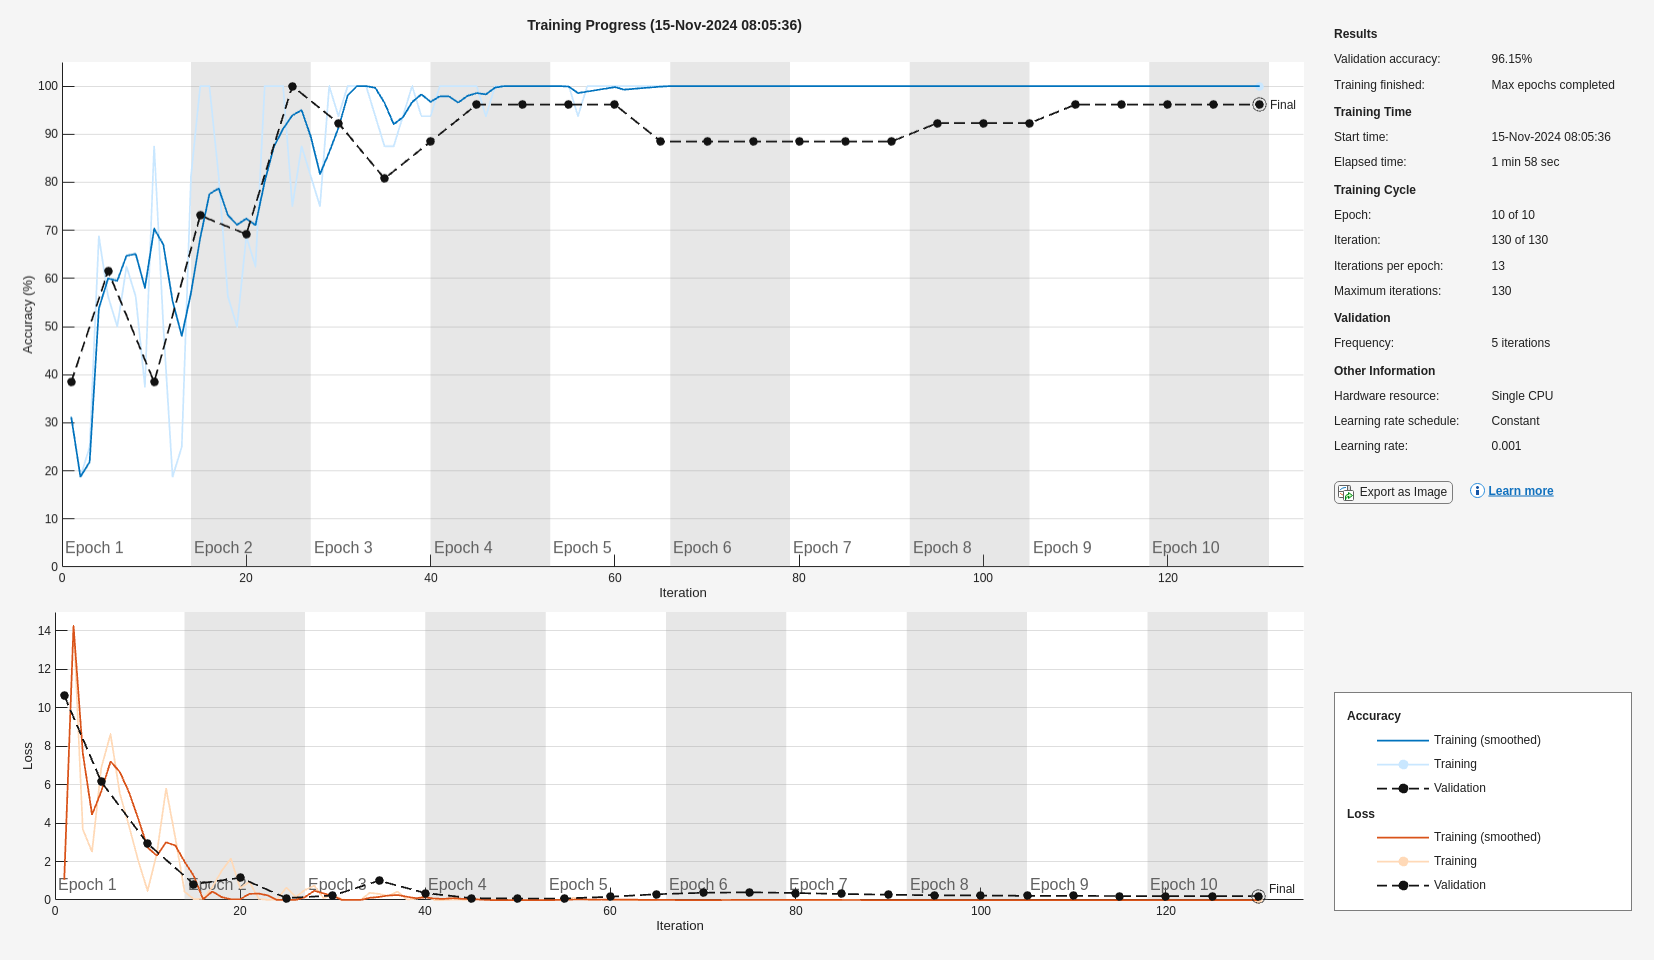

net = trainNetwork(XTrainSpecs, yTrain, layers, options);

predictedLabels = classify(net, XTestSpecs);

% Display accuracy
accuracy = sum(predictedLabels == yTest) / numel(yTest);
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 100%


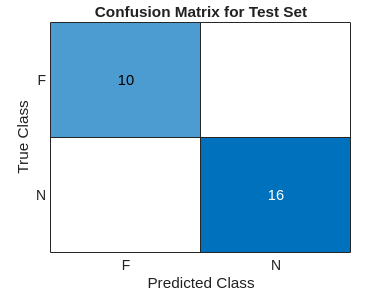


% Display the confusion matrix
figure;
confusionchart(yTest, predictedLabels);
title('Confusion Matrix for Test Set');

save('net.mat', "net")

exportONNXNetwork(net, 'net.onnx');


**Upload**

%ip_url = 'https://10.64.68.210:5000';
ip_url = 'http://192.168.21.251:5000';
url = sprintf('%s/login', ip_url);
postData = struct('username', 'password', 'password', 'username'); % replace with actual values
options = weboptions('MediaType', 'application/json');
response = webwrite(url, postData, options);
% Define the URL for the POST request
url = sprintf('%s/upload', ip_url);
token = response.access_token;
filePath = 'net.onnx';

% Define the curl command as a string
curl_command = sprintf(['curl -X POST -H "Authorization: Bearer %s" -F "file=@%s" %s'], ...
    token, filePath, url);

% Execute the curl command
[status, result] = system(curl_command);

% Display the result
if status == 0
    disp('File uploaded successfully');
    disp(result); % The response from the server
else
    disp('Failed to upload file');
    disp(result); % Error message
end

File uploaded successfully


curl: /home/entity014/matlab_program/bin/glnxa64/libcurl.so.4: no version information available (required by curl)
{
  "file_id": "6736ef3ddce3710153a9a8b4"
}

